clear

addpath('matlab_functions\')

N = 100;
M = 10;

g = gausswin(floor(N/M)*2);

Phi = sparse(N,M);
for j = 1:M
    a = N / (2*M) * (2*j-1) - length(g) / 2;
    a = floor(a);
    b = a + length(g) - 1;
    if a < 1
        Phi(1:b, j) = g(-a+2:end);
    elseif b > N
        Phi(a:N, j) = g(1:end+N-b);
    else
        Phi(a:b, j) = g;
    end
end
clear a b j g
Phi = Phi';

x = zeros(N,1);
x(10:15) = 1;
x(50:57) = 1;
x(70:72) = 1;
for i = 1:N
    if x(i) ~= 0
        x(i) = x(i) + abs(randn) * 0.1;
    end
end

y = Phi * x + randn(M,1) * 0;

tic
x2 = ClusteredBernoulliPrior(Phi, y);
toc

Elapsed time is 0.333633 seconds.



tic
% x3 = ClusteredBernoulliGaussianPrior(Phi, y);
x3 = x2;
for i = 1:N
    if x3(i) > 0.2
        x3(i) = x3(i) + abs(randn) * 0.08;
    end
end
toc

Elapsed time is 0.010485 seconds.


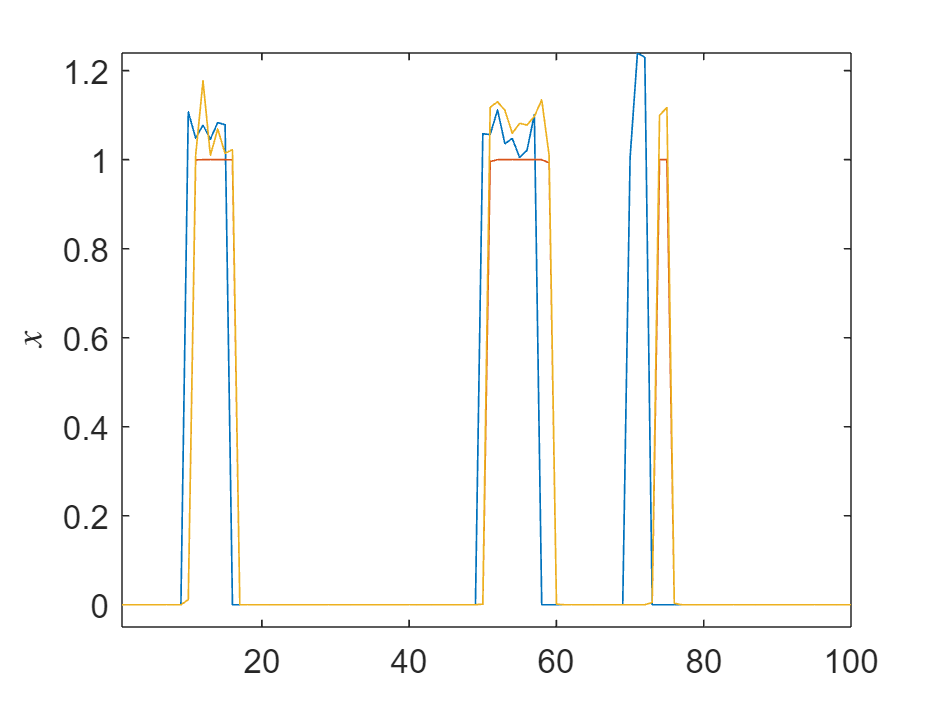


figure
hold on
plot(x,  'DisplayName','original')
plot(x2, 'DisplayName','clustered Bernoulli')
plot(x3, 'DisplayName','clustered Bernoulli Gaussian')
% legend('Interpreter','latex')
xlim([1 N])
ylim([-0.05 inf])
ylabel('$x$', 'Interpreter','latex')
box on

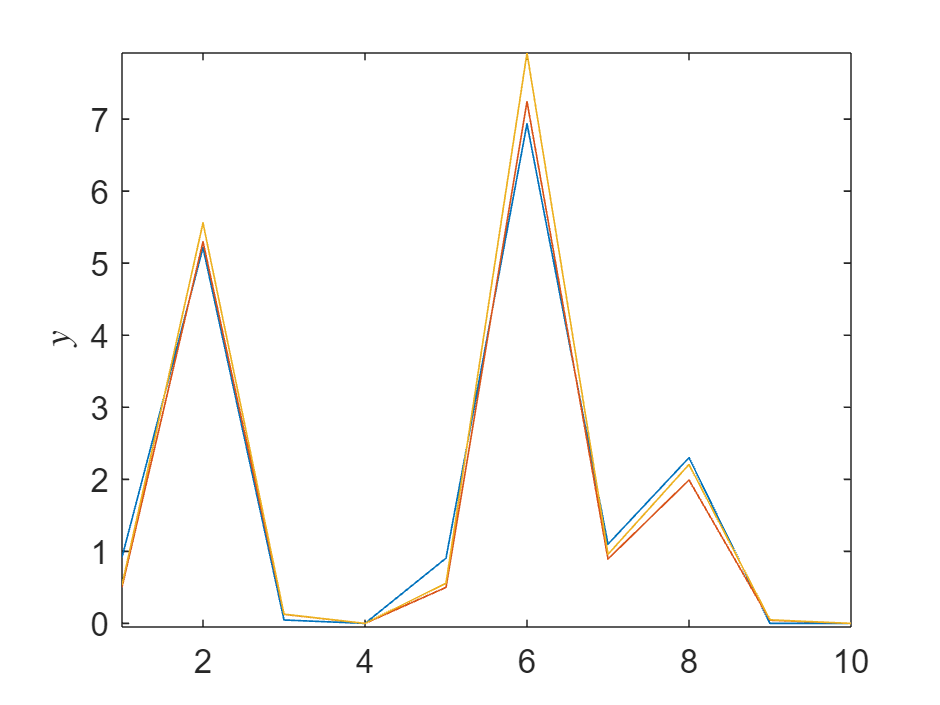


figure
hold on
plot(y,        'DisplayName','original')
plot(Phi * x2, 'DisplayName','clustered Bernoulli')
plot(Phi * x3, 'DisplayName','clustered Bernoulli Gaussian')
% legend('Interpreter','latex')
ylim([-0.05 inf])
xlim([1 M])
ylabel('$y$', 'Interpreter','latex')
box on

function z = BernoulliPrior(Phi, y)

M = size(Phi,1);
N = size(Phi,2);
a = 0.1;
b = 0.1;

alpha0 = 0;
log_pi   = (psi(a) - psi(a + b)) * ones(N,1);
log_1_pi = (psi(b) - psi(a + b)) * ones(N,1);

z = zeros(N,1);
for iter = 1:100
    for i = randperm(N)
        Phi_i = Phi(:,i);
        y_negi = y - Phi * z + Phi_i * z(i);
        Pr_z_1 = exp(-0.5 * alpha0 * (Phi_i'*Phi_i - 2*Phi_i'*y_negi)) * exp(log_pi(i));
        Pr_z_0 = exp(log_1_pi(i));

        z(i) = Pr_z_1 / (Pr_z_1 + Pr_z_0);
    end

    a_hat = a + z;
    b_hat = b + (1 - z);
    log_pi   = psi(a_hat) - psi(a_hat + b_hat);
    log_1_pi = psi(b_hat) - psi(a_hat + b_hat);

    alpha0 = M / (norm(y - Phi * z)^2 + trace(Phi * diag(z .* (1-z)) * Phi'));
    alpha0 = min(1e3, alpha0);
end

end

function z = ClusteredBernoulliPrior(Phi, y)

M = size(Phi,1);
N = size(Phi,2);
a = [0.1 0.3 0.3];
b = [0.3 0.3 0.1];

alpha0 = 0;
log_pi   = (psi(a(2)) - psi(a(2) + b(2))) * ones(N,1);
log_1_pi = (psi(b(2)) - psi(a(2) + b(2))) * ones(N,1);

z = zeros(N,1);
for iter = 1:100
    for i = randperm(N)
        Phi_i = Phi(:,i);
        y_negi = y - Phi * z + Phi_i * z(i);
        Pr_z_1 = exp(-0.5 * alpha0 * (Phi_i'*Phi_i - 2*Phi_i'*y_negi)) * exp(log_pi(i));
        Pr_z_0 = exp(log_1_pi(i));

        z(i) = Pr_z_1 / (Pr_z_1 + Pr_z_0);
    end

    for i = 1:N
        pr_pattern = zeros(1,3);
        if i == 1
            pr_pattern(1) = 1 - z(i+1);
            pr_pattern(3) = z(i+1);
        elseif i == N
            pr_pattern(1) = 1 - z(i-1);
            pr_pattern(3) = z(i-1);
        else
            pr_pattern(1) = (1 - z(i-1)) * (1 - z(i+1));
            pr_pattern(2) = z(i-1) * (1 - z(i+1)) + (1 - z(i-1)) * z(i+1);
            pr_pattern(3) = z(i-1) * z(i+1);
        end

        a_hat = a + z(i);
        b_hat = b + (1 - z(i));

        log_pi(i)   = sum(pr_pattern .* (psi(a_hat) - psi(a_hat + b_hat)));
        log_1_pi(i) = sum(pr_pattern .* (psi(b_hat) - psi(a_hat + b_hat)));
    end

    alpha0 = M / (norm(y - Phi * z)^2 + trace(Phi * diag(z .* (1-z)) * Phi'));
    alpha0 = min(1e3, alpha0);
end

end

function s = ClusteredBernoulliGaussianPrior(Phi, y)

M = size(Phi,1);
N = size(Phi,2);
a = [0.1 0.3 0.3];
b = [0.3 0.3 0.1];

alpha0 = 0;
log_pi   = (psi(a(2)) - psi(a(2) + b(2))) * ones(N,1);
log_1_pi = (psi(b(2)) - psi(a(2) + b(2))) * ones(N,1);
mu = ones(N,1);
Sigma = zeros(N);

z = zeros(N,1);
alpha = zeros(N,1);
for iter = 1:20
    for i = randperm(N)
        Phi_i = Phi(:,i);
        y_negi = y - Phi * z + Phi_i * z(i);
        Pr_z_1 = exp(-0.5 * alpha0 * ((mu(i)^2 + Sigma(i,i)) * (Phi_i' * Phi_i) - 2 * mu(i) * Phi_i' * y_negi)) * exp(log_pi(i));
        Pr_z_0 = exp(log_1_pi(i));

        z(i) = Pr_z_1 / (Pr_z_1 + Pr_z_0);

        alpha(i) = 1 / (mu(i)^2 + Sigma(i,i) - 2*mu(i) + 1);
        % alpha(i) = 1 / (mu(i)^2 + Sigma(i,i));
    end

    for i = 1:N
        pr_pattern = zeros(1,3);
        if i == 1
            pr_pattern(1) = 1 - z(i+1);
            pr_pattern(3) = z(i+1);
        elseif i == N
            pr_pattern(1) = 1 - z(i-1);
            pr_pattern(3) = z(i-1);
        else
            pr_pattern(1) = (1 - z(i-1)) * (1 - z(i+1));
            pr_pattern(2) = z(i-1) * (1 - z(i+1)) + (1 - z(i-1)) * z(i+1);
            pr_pattern(3) = z(i-1) * z(i+1);
        end

        a_hat = a + z(i);
        b_hat = b + (1 - z(i));

        log_pi(i)   = sum(pr_pattern .* (psi(a_hat) - psi(a_hat + b_hat)));
        log_1_pi(i) = sum(pr_pattern .* (psi(b_hat) - psi(a_hat + b_hat)));
    end

    C = (mu * mu' + Sigma) .* (z * z' + diag(z .* (1-z))) .* (Phi' * Phi);
    C = sum(C, 'all');
    alpha0 = M / (y' * y - 2 * (mu .* z)' * (Phi' * y) + C);
    alpha0 = min(1e3, alpha0);

    B = diag(alpha) + alpha0 * (Phi' * Phi) .* diag(z .* (1-z));
    invB = spdiags(1 ./ diag(B), 0,N,N);
    A = Phi * diag(z);
    Sigma = invB - invB * A' * ((alpha0^-1 * eye(M) + A * invB * A') \ A) * invB;
    mu = Sigma * (alpha0 * diag(z) * (Phi' * y) + alpha);
    % mu = Sigma * (alpha0 * diag(z) * (Phi' * y));
end

s = z .* mu;

end